# Throwing a Ball

## Introduction

I need to figure out how  long a ball will stay in the air. I can only remember one of the SUVAT equations however...

tic
clearvars
warning('off','symbolic:solve:SolutionsDependOnConditions')
syms a t real
syms s [1 2] real
syms v [1 2] real
assumeAlso(t>0)
assumeAlso(a<0)

## Time of Flight

One of equations of motion is as follows:

eqVUAT = v(2) == v(1) +a*t

$$eqVUAT = v_{2}=v_{1}+a\,t$$

To get the another equation of motion, we integrate the above equation with respect to time to get the difference in displacement. $s_2 -s_1 =\int_0^t v_2 \mathrm{dt}$

eqSUAT = s(2)-s(1) == int(rhs(eqVUAT),t,0,t)

$$eqSUAT = s_{2}-s_{1}=\frac{a\,t^{2}}{2}+v_{1}\,t$$

Rearranging the above equation in terms of time $t$:

eqSUAT = isolate2(eqSUAT,t,2)

$$eqSUAT = t=-\frac{v_{1}+\sqrt{{v_{1}}^{2}-2\,a\,s_{1}+2\,a\,s_{2}}}{a}$$

Substituting the following values, we get the time of flight.

u = symunit;

values = {
v(1), 30*sin(30*u.deg)*u.mph
a, -9.81*u.m/u.s^2
s(1),0*u.m
s(2),0*u.m
};

eqSubs(eqSUAT,values(:,1),values(:,2),"US",3)

$$ans = t=1.37\,s$$

## 2D Throw

Let's rejig the analysis to determine the optimum angle the ball should be thrown to cover the furthest horizontal distance.

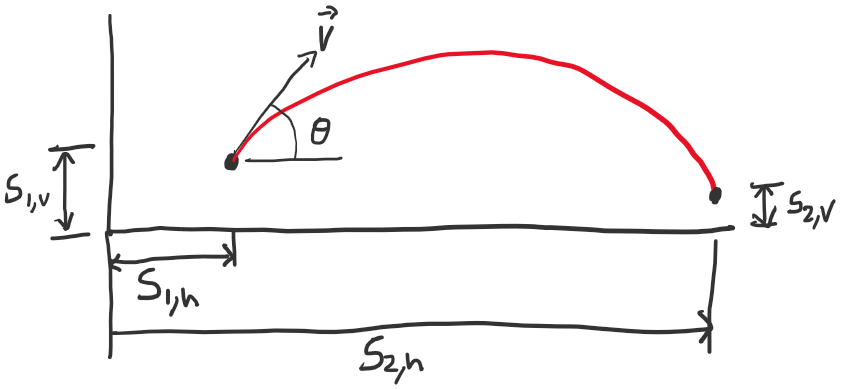

The horizontal and vertical equations of motion are as follows:

syms s_1_h s_1_v s_2_h s_2_v a_h a_v real
syms theta positive real
assumeAlso(a_v<0)
assumeAlso(a_h<=0)
assumeAlso(theta<pi/2)
assumeAlso(v(1)>0)

eqSUAT2D = isolate(eqSUAT,s(2));
eqSUAT2D = subs(eqSUAT2D,{s(2), s(1),v(1),a},{[s_2_h, s_2_v],[s_1_h,s_1_v],[v(1)*cos(theta),v(1)*sin(theta)],[a_h,a_v]})

$$eqSUAT2D = \left(\begin{array}{cc} s_{2,h}=\frac{a_{h}\,t^{2}}{2}+v_{1}\,\cos\left(\theta \right)\,t+s_{1,h} & s_{2,v}=\frac{a_{v}\,t^{2}}{2}+v_{1}\,\sin\left(\theta \right)\,t+s_{1,v} \end{array}\right)$$

The values to be substituted are:

values = {
a_h, 0*u.m/(u.s)^2
a_v, -9.81*u.m/(u.s)^2
v(1), 13.41*u.m/u.s
s_1_h, 0*u.m
s_1_v, 2*u.m
s_2_v, 0*u.m
s_2_h, s_2_h*u.m
theta, 45*u.deg
t, t*u.s
};

For the above values, the trajectory is plotted below:

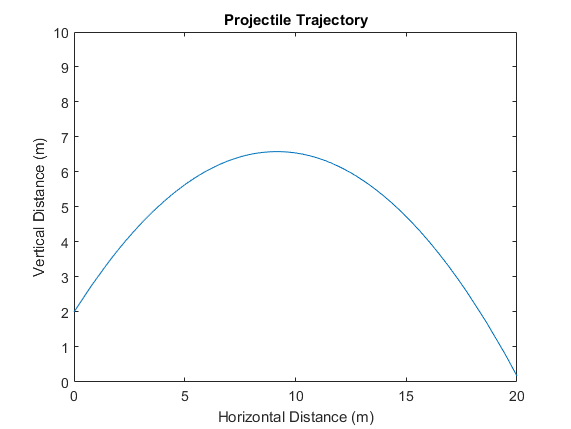

eqSUAT2Dsubs = separateUnits(unitConvert(subs(eqSUAT2D,values(:,1),values(:,2)),"SI"));
eqTime = isolate2(eqSUAT2D(2),t,2);
timeofflight = eqSubs(eqTime,values(:,1),values(:,2),'SI',3);
%converting time of flight into a double precision type
timeofflight = double(rhs(timeofflight));
fplot(rhs(eqSUAT2Dsubs(1)),rhs(eqSUAT2Dsubs(2)),[0,10])
xlabel('Horizontal Distance (m)')
ylabel('Vertical Distance (m)')
title('Projectile Trajectory')
xlim([0,20])
ylim([0,10])

## Optimising the angle

To optimise the distance the ball travels, we need to solve $\frac{\partial s_{2,h}}{\partial \theta} = 0$. However, the **horizontal** equation of motion (shown below) is a function of the time of flight ($t$) which is a function of $\theta$, and hence needs to be substituted.

eqSUAT2D

$$eqSUAT2D = \left(\begin{array}{cc} s_{2,h}=\frac{a_{h}\,t^{2}}{2}+v_{1}\,\cos\left(\theta \right)\,t+s_{1,h} & s_{2,v}=\frac{a_{v}\,t^{2}}{2}+v_{1}\,\sin\left(\theta \right)\,t+s_{1,v} \end{array}\right)$$

The time of flight $t$ can be determined by rearranging the **vertical **equation of motion:

eqTime

$$eqTime = t=-\frac{\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}+v_{1}\,\sin\left(\theta \right)}{a_{v}}$$

Substituting the time of flight $t$ into the **horizontal** equation of motion, we get the following:

eqDistanceTravelled =subs(eqSUAT2D(1),lhs(eqTime),rhs(eqTime))

$$eqDistanceTravelled = s_{2,h}=s_{1,h}+\frac{a_{h}\,{\left(\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}+v_{1}\,\sin\left(\theta \right)\right)}^{2}}{2\,{a_{v}}^{2}}-\frac{v_{1}\,\cos\left(\theta \right)\,\left(\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}+v_{1}\,\sin\left(\theta \right)\right)}{a_{v}}$$

Differentiating the above with respect to $\theta$, we get the following:

values{[values{:,1}] == theta,2} = theta;
dfDistanceTravelled(theta) = simplify(diff(rhs(eqDistanceTravelled),theta))

$$dfDistanceTravelled(theta) = \begin{array}{l} \frac{v_{1}\,\sin\left(\theta \right)\,\left(\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}+v_{1}\,\sin\left(\theta \right)\right)}{a_{v}}-\frac{v_{1}\,\cos\left(\theta \right)\,\sigma_{1}}{a_{v}}+\frac{a_{h}\,\sigma_{1}\,\left(\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}+v_{1}\,\sin\left(\theta \right)\right)}{{a_{v}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=v_{1}\,\cos\left(\theta \right)+\frac{{v_{1}}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sqrt{{v_{1}}^{2}\,{\sin\left(\theta \right)}^{2}-2\,a_{v}\,s_{1,v}+2\,a_{v}\,s_{2,v}}} \end{array}$$

MATLAB isn't able to solve the above equation due to the complexity (and possibly because there aren't enough assumptions to help reduce the solution space). We have two options:

### Numerical Solution

We can solve numerically by substituting the numerical values for all variables except for $\theta$. This gives us the following expression for $\frac{\partial s_{2,h}}{\partial \theta}$.

dfDistanceTravelledsubs = simplify(subs(dfDistanceTravelled,values(:,1),values(:,2)))

$$dfDistanceTravelledsubs(theta) = \frac{447\,\left(312418\,\sin\left(\theta \right)-799236\,{\sin\left(\theta \right)}^{3}+894\,\cos\left(2\,\theta \right)\,\sqrt{243409-199809\,{\cos\left(\theta \right)}^{2}}\right)}{21800\,\sqrt{243409-199809\,{\cos\left(\theta \right)}^{2}}}\,m$$

Setting $\frac{\partial s_{2,h}}{\partial \theta}=0$ and solving for $\theta$ gives the following optimum angle.

vpa(unitConvert(vpasolve(separateUnits(dfDistanceTravelledsubs==0),theta,[0,pi/2])*u.rad,u.deg),3)

$$ans = 42.2\,\deg$$

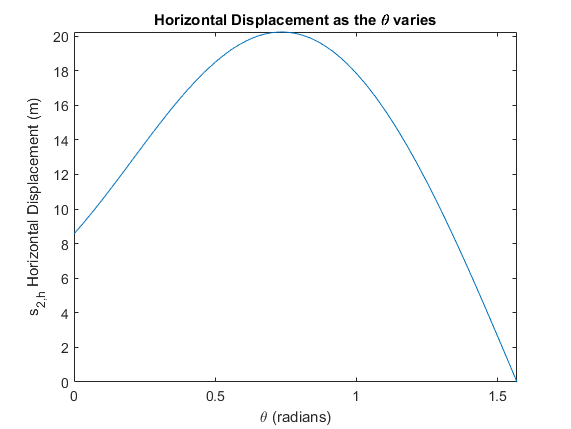

fDistanceTravelledsubs = separateUnits(unitConvert(rhs(subs(eqDistanceTravelled,values(:,1),values(:,2))),"SI"));
fplot(fDistanceTravelledsubs,[0,pi/2])
xlabel('{\theta} (radians)')
ylabel('{s_{2,h}} Horizontal Displacement (m)')
title('Horizontal Displacement as the {\theta} varies')

### Special Case

We can take a special case where the horizontal acceleration $a_h$ is 0, and the start and end displacements $s_{1,h}$,  $s_{2,h}$ are also 0. In this case $\frac{\partial s_{2,h}}{\partial \theta}$ reduces to the following:

dfDistanceTravelledSpecial(theta) = simplify(subs(dfDistanceTravelled,{a_h, s_1_v, s_2_v},{0,0,0}))

$$dfDistanceTravelledSpecial(theta) = -\frac{2\,{v_{1}}^{2}\,\cos\left(2\,\theta \right)}{a_{v}}$$

Setting $\frac{\partial s_{2,h}}{\partial \theta} = 0$ and solving for $\theta$, we get the optimum angle for the furthest horizontal displacement.

isolate(dfDistanceTravelledSpecial==0,theta)

$$ans = \theta =\frac{\pi }{4}$$

toc

Elapsed time is 3.109955 seconds.


function exout = eqSubs(exin, symbols, values, units, precision)
    exout = vpa(simplify(unitConvert(subs(exin,symbols,values),units)),precision);
end

function exout = isolate2(exin,var,solutionnumber)
    sol = solve(exin,var);
    exout = var == sol(solutionnumber);
end